% Putting together pretty much all the code for my manuscript figs
% on one doc

addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\in_progress_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\code_shared_groupNind
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\individual_analysis_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\group_analyses_code

% starting w code for individual mice/session

% MANUALLY navigate to widefield/date_animalID folder

## LOADING MAPS VARS & BALL DATA

% load maps file for recording session (maps file generated by dfofMovie)
[df,frameT] = loadStage2MapsVars();

% load stimulus session data (comes from ballData folder on stimulus presentation computer)
[subjData,sessionFile,allStop,allResp,stimDetails,trialCond] = loadStage2subjSessVars();

% create figure title info
[date,subjName] = createTitleInfo(sessionFile,subjData);

## CHECK FRAME RATES

% check imaging & monitor frame rate
[percentSlippedImagingFrames,timeStampsStopAndRespFramesAlltrialsMinusT0,percentSlippedMonitorFrames] = checkImagingAndMonitorFrames(frameT,allStop,allResp,subjName,date);

## CROP FLUORESCENCE MOVIE

% check broad activity over whole field of view
meanDfEntireFOVvsFrames_wholeSessAnd1min(df,subjName,date);

% pick the image/adjust the range on the image to be used for cropping in following step
[range,colorMapOrNot] = pickImageToCrop(df,subjName,date);

% crop image/movie & show cropped image
[xPtsCrop,yPtsCrop,dfCROP] = doCrop(df,range,colorMapOrNot,date,subjName);

## SEGMENT BY STIM ONSET

% get time of stimulus onsets for each trial
[stimOnsets] = onsetsStimFrames(allStop,allResp);

% how many early & late trials to filter out? change this in this meta script if need
earliestTrial = 6
numLateTrialsSubtract = 5

% filter first and last few trials... can change num trials in code
[idxOnsetsMeetsCriteria,filteredStimOnsets] = filterOnsets_removeEarlyAndLateTrials(stimOnsets,earliestTrial,numLateTrialsSubtract);

% for each trial, get the indicies for the 1st imaging frame that folows the stimulus onset
[onsetImFrames] = onsetImagingFrames(filteredStimOnsets,frameT);

% picking pre & post imaging frames for indexing dfCROP into "chunks"

numPreStimFrames = 3
numPostStimFrames = 14

% make onsetDf variable
% use the indicies for the 1st imaging frame follwing stimulus onset, 
% plus the num pre & post frames defined earlier in this script,
% to index into dF % take 'chunks' of video around each stim onset
[onsetDf] = makeOnsetDf(onsetImFrames,dfCROP,numPreStimFrames,numPostStimFrames);

## GET STIM PARAMS for LOOPS and LEGENDS

% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend

% pick the baseline indicies, show the mean baseline image, subtract from pix wise onsetDf
% images to demonstrate that these baseline indicies are appropriate. Diagnostic figures. 
% go in fcn and change 'baselineIdx' if want diff baseline range
[stimOnsetFrame,baselineIdx] = pickBaselineIdx(numPreStimFrames,conOrderedByTrialMeetCriteria,uniqueContrasts,date,subjName,onsetDf) 

% now do similar - show that subtracting mean basline values works as expected, but
% plot mean (over trials) df of entire (cropped) imageing view vs frames (regular graph, not pixel wise)
plotPrePostBaselineOnsetDfVsFrames(onsetDf,date,subjName,baselineIdx);

% show pix wise peri stim pre & post baseline-ing
showPixWisePeriStimPrePostBaseline(conOrderedByTrialMeetCriteria,uniqueContrasts,onsetDf,baselineIdx,date,subjName)

%print('allStims_fig.png','-dpng')

## MAKE PERI-STIM ACTIVITY MAPS PER CON & PER DUR

% % pix wise peri stim  per stim cond (con only then dur only)
% showPixWiseByStimConds(stimOnsetFrame,date,subjName,uniqueContrasts,conOrderedByTrialMeetCriteria,onsetDf,baselineIdx,uniqueDurations,durOrderedByTrialMeetCriteria);
% %print('groupPupRunScatter_fig.png','-dpng')

% peri stim con
showPixWisePeriStim_CON(stimOnsetFrame,date,subjName,uniqueContrasts,conOrderedByTrialMeetCriteria,onsetDf,baselineIdx,uniqueDurations,durOrderedByTrialMeetCriteria);
%print('periStimCON.png','-dpng')

showPixWisePeriStim_DUR(stimOnsetFrame,date,subjName,uniqueContrasts,conOrderedByTrialMeetCriteria,onsetDf,baselineIdx,uniqueDurations,durOrderedByTrialMeetCriteria);
%print('periStimDUR.png','-dpng')

## PEAK ACTIVITY  MAPS PER STIM COND

% define peak activity frames (can change num frames in code, default is 10 frames post-stim onset frame)
numPeakFrames = 3;
[peakFrameIdx] = pickPeakFrames(stimOnsetFrame+1,numPeakFrames)

% show peak pix wise activity for each stim condition (con/dur combo)
showPixWisePeakActivityPerStimCond(date,subjName,uniqueContrasts,uniqueDurations,conAndDurOrderedByTrialMeetCriteria,peakFrameIdx,onsetDf,baselineIdx);
%print('peakActPerStimCOND.png','-dpng')

## POINTS FOR ANALYSIS

% Pick image to be used to pick points in visual areas in next step
[baselinedActIm,range,colorMapOrNot] = pickPeakActIm4Points(conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations,peakFrameIdx,onsetDf,baselineIdx);

% THIS PART NOT COMPLETE 
% Make 3 IMAGE to help idenitfy visual areas & blood vessels...
% first run do_topo, which needs the recording session to be un-commented in batch file
formatSpec = '%s%s%s';
dateNoSpaces = sprintf(formatSpec,date(1:2),date(4:5),date(9:10));
[meanpolar,ypts,xpts] = do_topo(subjName,dateNoSpaces);

% now SHOW the fig (despite that the name of the function says)
% CHANGE the tif file/folder path in ehere each time
visArea = 1:length(RoundYpts)
global visArea
global RoundXpts
global RoundYpts
[tifPic] = pickVisAreaPts3figs_051022test(meanpolar,ypts,xpts,baselinedActIm,df,range);

% actually pick the points
[xPickedPts,yPickedPts] = pickVisAreaPts(baselinedActIm,range,colorMapOrNot);

% make PTSdfof - this time I took the *mean over 25 pix squared (5x5 pix area)* for each point
[RoundXpts,RoundYpts,PTSdfof] = makePTSdfof(xPickedPts,yPickedPts,onsetDf,range,colorMapOrNot);

% THIS PART NOT WORKING RIGHT FOR SOME REASON...

range = [0 0.07];
colorMapOrNot = 1;

visArea = 1
%visArea = 1:length(RoundXpts);

figure

imagesc(baselinedActIm,range)

if colorMapOrNot == 1
    colormap jet
end 

axis equal

hold on
    
% 1st point - each pt is one pixel 
%[RoundXpts(1,1),RoundYpts(1,1)]
% horizontal line, plus or minus 5 verical pixels
devitation = 3;
for i = visArea
    x = [RoundXpts(1,i)-devitation:1:RoundXpts(1,i)+devitation];
    y1 = [(RoundYpts(1,i)+devitation)*ones(1,length(x))];
    y2 = [(RoundYpts(1,i)-devitation)*ones(1,length(x))];
end

plot(x,y1,'w','lineWidth',2)
hold on
plot(x,y2,'w','lineWidth',2)
hold on

for i = visArea
    x1 = [(RoundXpts(1,i)+devitation)*ones(1,length(x))];
    x2 = [(RoundXpts(1,i)-devitation)*ones(1,length(x))];
    y = [RoundYpts(1,i)-devitation:1:RoundYpts(1,i)+devitation];
end

plot(x1,y,'w','lineWidth',2)
hold on 
plot(x2,y,'w','lineWidth',2)


% SAME AS ABOVE BUT WORKS BETTER... MAYBE UNCOMMENT AXES?

% Plot boxes over points picked
range = [0 0.095];
colorMapOrNot = 1;
visArea = 1:length(RoundXpts);

figure
imagesc(baselinedActIm,range)
if colorMapOrNot == 1
    colormap jet
end 

axis equal
%colorbar
set(gca,'Visible','off') % turning axes off made boxes black!

hold on
    
% note: 1st point - each pt is one pixel 
%[RoundXpts(1,1),RoundYpts(1,1)]
% horizontal line, plus or minus 5 verical pixels

devitation = 2;

for i = visArea

    x = [RoundXpts(1,i)-devitation:1:RoundXpts(1,i)+devitation];
    y1 = [(RoundYpts(1,i)+devitation)*ones(1,length(x))];
    y2 = [(RoundYpts(1,i)-devitation)*ones(1,length(x))];
    
    % reverse x & y...
    plot(y1,x,'w','lineWidth',2)
    hold on
    plot(y2,x,'w','lineWidth',2)
    hold on
    
    x1 = [(RoundXpts(1,i)+devitation)*ones(1,length(x))];
    x2 = [(RoundXpts(1,i)-devitation)*ones(1,length(x))];
    y = [RoundYpts(1,i)-devitation:1:RoundYpts(1,i)+devitation];
    
    % reverse x & y...
    plot(y,x1,'w','lineWidth',2)
    hold on 
    plot(y,x2,'w','lineWidth',2)
    
    hold on 
    
end % end i loop

hold on 

% set(gca, 'FontSize', 18, 'FontName', 'Times')
% xlabel('$pixels$', 'Interpreter', 'latex')
% ylabel('$pixels$', 'Interpreter', 'latex')

%clear xt
%xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
% set(gca,'xtick',0:20:100); 
% set(gca,'ytick',20:20:120); 
%set(gca,'xticklabel',xt);


% save plot
%print('305RT_070421_points_picked.png','-dpng')

% visualization

%grid on

% fntSize = 8;
% fntName = 'SansSerif';
% 
% set(gca, 'FontSize', fntSize, 'FontName', fntName)
% 
% fontMult = 1.5;
% 
% ylabel('pixels', 'FontSize', fntSize*fontMult, 'FontName', fntName)
% yt = [20:20:120];
% ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
% set(gca,'YTick',yt)
% set(gca,'YTickLabel',ytl)
% 
% xlabel('pixels', 'FontSize', fntSize*fontMult, 'FontName', fntName)
% xt = [0:20:100];
% xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
% set(gca,'xtick',xt); 
% set(gca,'xticklabel',xtl);

%legend('pupil size','pupil threshold', 'FontName', fntName)

% save plot
%print('pickedPoint_124LT_071521_expt1_jet.png','-dpng')


## GET NON-SEGMENTED V1 DF TRACE FOR ENTIRE RECORDING

## (for pupil analysis)

% note that there is no way to baseline a trace for the entire recording...

clear dfofV1Point
dfofV1Point(1,:,:) = dfCROP(RoundXpts(1),RoundYpts(1),:,:);

sizeDfofV1Point = size(dfofV1Point)

## RUNNING ANALYSIS

% x & y coordinates, run path
[allXYcursorCoordinatesStopAndRespFramesAlltrials] = stitchBackCursorCoordinatesForAllTrialsAndFrames(allStop,allResp);

% calculate mean run speed for each trial
[meanSpeedAllTrials] = calcMeanRunSpeedAllTrials(allStop,allResp);

% BAR plot of same^

figure
bar(meanSpeedAllTrials)
xlabel('trials')
ylabel('mean running speed')
title('mean running speed vs ALL trials')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])

figure
xRangeMin = 800;
xRangeMax = 1000;
bar(meanSpeedAllTrials(1,xRangeMin:xRangeMax))
xlabel('trials')
ylabel('mean running speed')
title('mean running speed vs 200 trials')
xlim([0 length(meanSpeedAllTrials(1,xRangeMin:xRangeMax))])
ylim([-5 500])

%histogram(meanSpeedAllTrials);
%numBins = 10;
%histogram(meanSpeedAllTrials,numBins)
%histogram(meanSpeedAllTrials,numBins,'normalization','probability')
%histogram(meanSpeedAllTrials,'binWidth',20,'normalization','probability')

%Bin edges, specified as a vector. edges(1) is the left edge of the first bin, 
%and edges(end) is the right edge of the last bin.

edges = [0 0:25:max(meanSpeedAllTrials) max(meanSpeedAllTrials)];
%h = histogram(meanSpeedAllTrials,edges);
histogram(meanSpeedAllTrials,edges,'normalization','probability');
xlim([0 max(meanSpeedAllTrials)])
ylabel('percent of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds - edges')

%Each bin includes the left edge, but does not include the right edge, 
%except for the last bin which includes both edges
%numedges = ;
%histogram(X,numedges)

% x = randn(1000,1);
% edges = [-2 -2:0.25:2 2];
% h = histogram(x,edges);

% running speed dist, alterable:
% HISTO showing FREQuency of different RUNning SPEEDs for FOR EVERY TRIAL

%numTrials = length(meanSpeedAllTrials)
numBins = 10

histogram(meanSpeedAllTrials,numBins,'normalization','probability')
ylabel('fraction of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds - bins')
xlim([0 round(max(meanSpeedAllTrials)+10)])
set(gca,'xtick',0:25:round(max(meanSpeedAllTrials)+10));
ylim([0 1])

% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials,earliestTrial,numLateTrialsSubtract);
sizemeanSpeedAllTrials = size(meanSpeedAllTrials)

% pick a threshold... what percentage of trials above & below it?
% based on histogram, I picked 60 pix/frame threshold for running

runThresh = 60;

numTrials = length(meanSpeedAllTrials)
numTrialsOverThresh = sum(meanSpeedAllTrials>=runThresh)
percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100

% the meanSpeedAllTrials vector has 1 row, each column has
% the mean speed for that trial (*not* onset chunk)
% note that resolution for cursor is 6 times higher than for 
% imaging, so the extra frames (all trials-onset chunk) don't
% count for as much (divide by 6)

% indicies for trials that meet our threshold
idxRunTrials = find(meanSpeedAllTrials>=runThresh);
numRunTrials = length(idxRunTrials);

% indicies for stationary trials
idxStatTrials = find(meanSpeedAllTrials<=runThresh);
numStatTrials = length(idxStatTrials)


## PUPIL ANALYSIS

% LOAD DLC/python PUPIL TRACKING data
[f p] = uigetfile('*.mat','REYE pupil track file');
load(fullfile(p,f));

% plot pupil diamter over time (in pix)
figure
plot(longaxis)
ylabel('diameter(pix)')
xlabel('frames (60 Hz)')
title('pupil diameter over time')

sizeLongAxis = size(longaxis,2)
sizeDf = size(df,3)


% ONSET SEGMENTING - 
% line up pupil dimater trace with V1 dfof trace for each
% stim onset chunk

% Index long axis with the values in onsetImFrames, 
% which are the indicies of imaging frames at the onset of a trial

% long axis is downsampled to 10Hz so time stamps are not needed,
% only imagaing frame indicies

% NOTE: onsetImFrames is already fitered away early & late trials so don't filter pupil diamters again

clear o
for o = 1:length(onsetImFrames)
    
    % select only the pupil frames right before & after the onset imaging frame of each stim
    eachOnsetPupil = longaxis(1,onsetImFrames(o)-numPreStimFrames:onsetImFrames(o)+numPostStimFrames);
    
    allOnsetPupils(o,:) = eachOnsetPupil;

end

%sizeOfEachOnsetPupil = size(eachOnsetPupil)
sizeOfAllOnsetPupils = size(allOnsetPupils)

sizeOfAllOnsetPupils =         1711          18


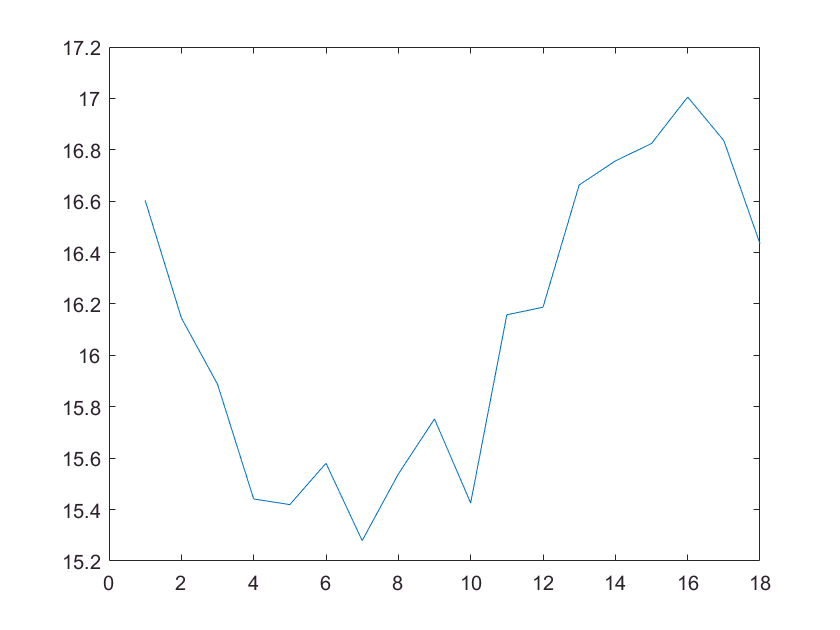


% plot one trial
figure
plot(allOnsetPupils(400,:))


% get mean pupil diamter for each trial

clear p 

for p = 1:length(allOnsetPupils)
    
    meanPupilDiameterEachTrial = nanmean(allOnsetPupils(p,:));
    meanPupilDiameterAllTrials(1,p) = meanPupilDiameterEachTrial;
    
end
sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

sizeMeanPupilDiameterAllTrials =            1        1711


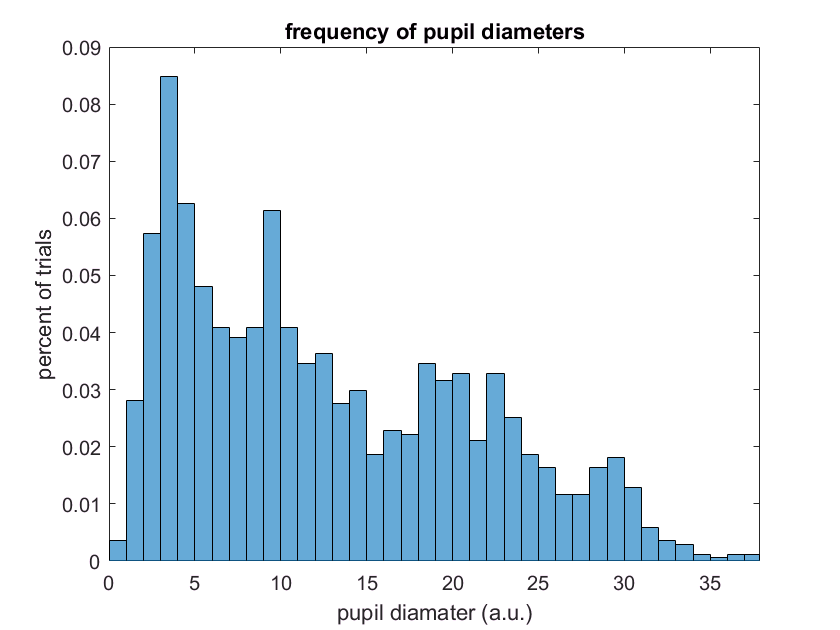


% Q: if I'm plotting group pupil histos next, I don't really want normalized yet do I?
% But different mice also have different sized pupils (no?) diff lighting conditions (no)?...
% noramlize pupil diamter to miniumum pupil diameter
meanPupilDiameterAllTrials = meanPupilDiameterAllTrials-min(meanPupilDiameterAllTrials);

% (DONT DO FOR PUPILS) FILTER first and last few trials... can change num trials in code
%[pupIdxOnsetsMeetsCriteria,meanPupilDiameterAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanPupilDiameterAllTrials,earliestTrial,numLateTrialsSubtract);
%sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

% histo of pupil diameter sizes
edges = [0 0:1:max(meanPupilDiameterAllTrials) max(meanPupilDiameterAllTrials)];
histogram(meanPupilDiameterAllTrials,edges,'Normalization','probability')
xlim([0 max(meanPupilDiameterAllTrials)])
title('frequency of pupil diameters')
xlabel('pupil diamater (a.u.)')
ylabel('percent of trials')

## RUN & PUPIL TOGETHER

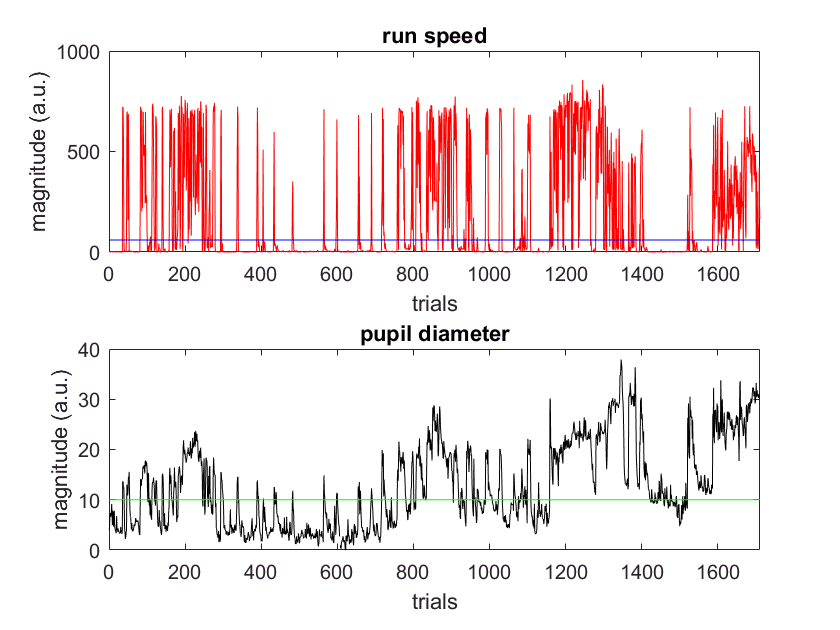

% run speed
x_axis = 1:length(meanSpeedAllTrials);
figure
subplot(2,1,1)
plot(x_axis,meanSpeedAllTrials,'r')
xlim([0 length(x_axis)])
ylabel('magnitude (a.u.)')
xlabel('trials')

hold on

% run thresh line
clear y
y(1,1:length(meanSpeedAllTrials)) = runThresh;
plot(1:length(y),y,'b')
title('run speed')
xlim([0 length(meanSpeedAllTrials)])

%pupil 
x_axis = 1:length(meanPupilDiameterAllTrials);
subplot(2,1,2)
plot(x_axis,meanPupilDiameterAllTrials,'k')

hold on 

% pup thresh line
clear y
y(1,1:length(meanPupilDiameterAllTrials)) = pupThreshold;
plot(1:length(y),y,'g')
title('pupil diameter')
xlim([0 length(meanPupilDiameterAllTrials)])
xlabel('trials')
ylabel('magnitude (a.u.)')

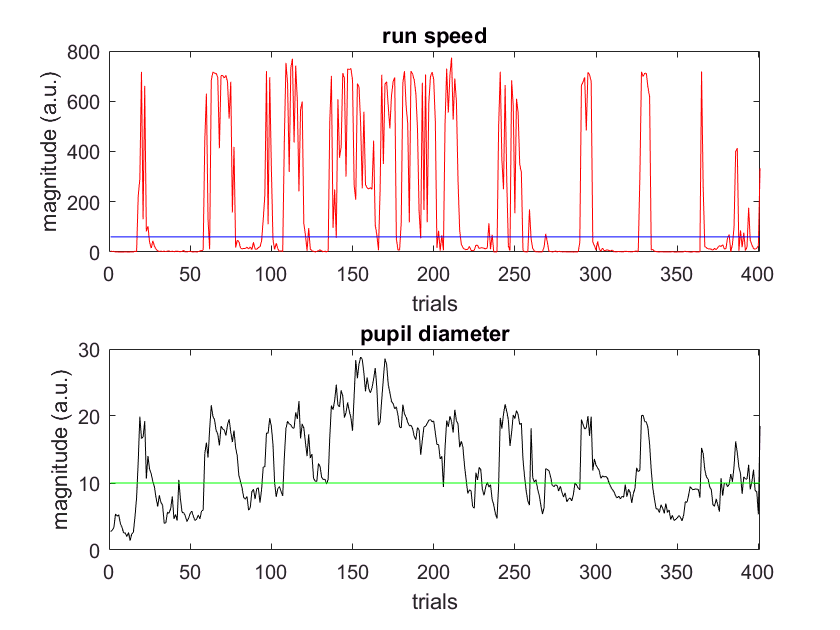


% above but smaller time range

startTrial = 700;
endTrial = 1100;
% run speed
x_axis = 1:length(meanSpeedAllTrials(1,startTrial:endTrial));
figure
subplot(2,1,1)
plot(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
xlim([0 length(x_axis)])
ylabel('magnitude (a.u.)')
xlabel('trials')

hold on

% run thresh line
clear y
y(1,1:length(meanSpeedAllTrials(1,startTrial:endTrial))) = runThresh;
plot(1:length(y),y,'b')
title('run speed')
xlim([0 length(meanSpeedAllTrials(1,startTrial:endTrial))])

%pupil 
x_axis = 1:length(meanPupilDiameterAllTrials(1,startTrial:endTrial));
subplot(2,1,2)
plot(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')

hold on 

% pup thresh line
clear y
y(1,1:length(meanPupilDiameterAllTrials(1,startTrial:endTrial))) = pupThreshold;
plot(1:length(y),y,'g')
title('pupil diameter')
xlim([0 length(meanPupilDiameterAllTrials(1,startTrial:endTrial))])
xlabel('trials')
ylabel('magnitude (a.u.)')

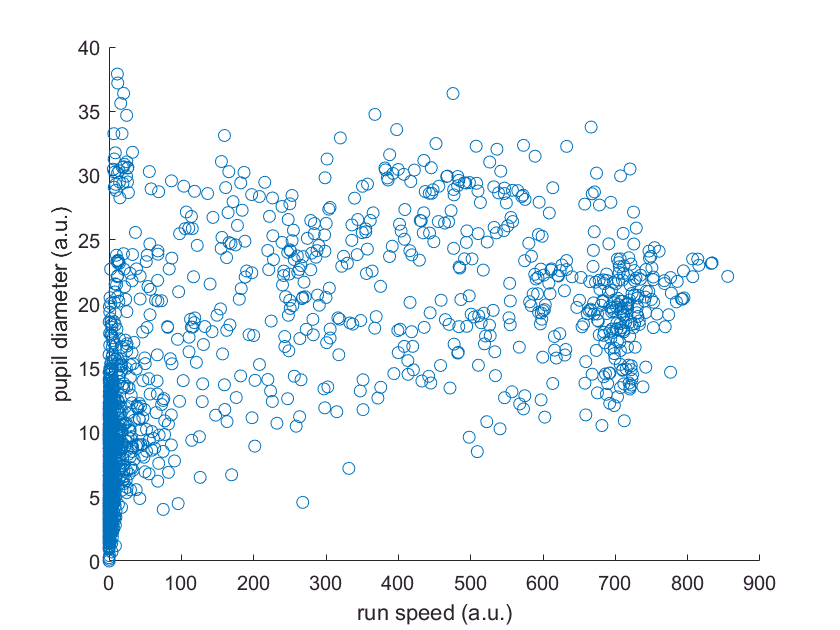



% SCATTER RUN VS PUP

figure
scatter(meanSpeedAllTrials,meanPupilDiameterAllTrials)
xlabel('run speed (a.u.)')
ylabel('pupil diameter (a.u.)')

## SAVE INDIVIDUAL VARS FOR GROUP/REST OF ANALYSIS

% ** NAVIGATE to correct folder **

%w/Pup
% save('121322_2ERT_newVars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetImFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','runThresh','idxRunTrials','idxStatTrials','runIdxOnsetsMeetsCriteria',...
%     'dfofV1Point','longaxis','allOnsetPupils','meanPupilDiameterAllTrials','pupThreshold',...
%     'idxSmallPupilTrials','idxLargePupilTrials','earliestTrial',...
%     'numLateTrialsSubtract','-v7.3') % '-append',

%save(121322_2ERT_newVars4IndAndGroupAnalyses.mat,'earliestTrial','-append')

% w/no Pup
% save('122821_G6CK2GRT_vars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetImFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','runThresh','idxRunTrials','idxStatTrials','runIdxOnsetsMeetsCriteria',...
%     'dfofV1Point',...
%     '-v7.3') % '-append',
